# The taslinksslinksslinkss linkssAB 5

## init

clear
clc
close all;
deg = pi/180;
LinkLength1 = 1;
LinkLength2 = 1;
LinkLength3 = 1;


## linkssINKS

linkss = Revolute(...
    'd', LinkLength1, 'a', 0, 'alpha', pi/2, ...
    'I', [0, 0, 0], 'm', 0, ...
    'Jm', 1e-4, 'G', 500, ...
    'B', 10e-4, 'Tc', 10e-4, ...
    'qlim', [-180 180]*deg);

ans = logical
   1




linkss = [linkss Revolute(...
    'd', 0, 'a', LinkLength2, 'alpha', 0,...
    'r', [0.5, 0, 0], 'I', [0.01, 0.8, 0.8], ...
    'm', 10, ...
    'Jm', 1e-4, 'G', 500, ...
    'B', 10e-4, 'Tc', 10e-4, ...
    'qlim', [-90 90]*deg)];

ans = logical
   1




linkss = [linkss Revolute('d', 0, 'a', LinkLength3, 'alpha', 0,...
    'r', [0.5, 0, 0], ...
    'I', [0.01, 0.8, 0.8], ...
    'm', 10, ...
    'Jm', 1e-4, ...
    'G', 500, ...
    'B', 10e-4, ...
    'Tc', 10e-4, ...
    'qlim', [-90 90]*deg)];

ans = logical
   1


## ROBT

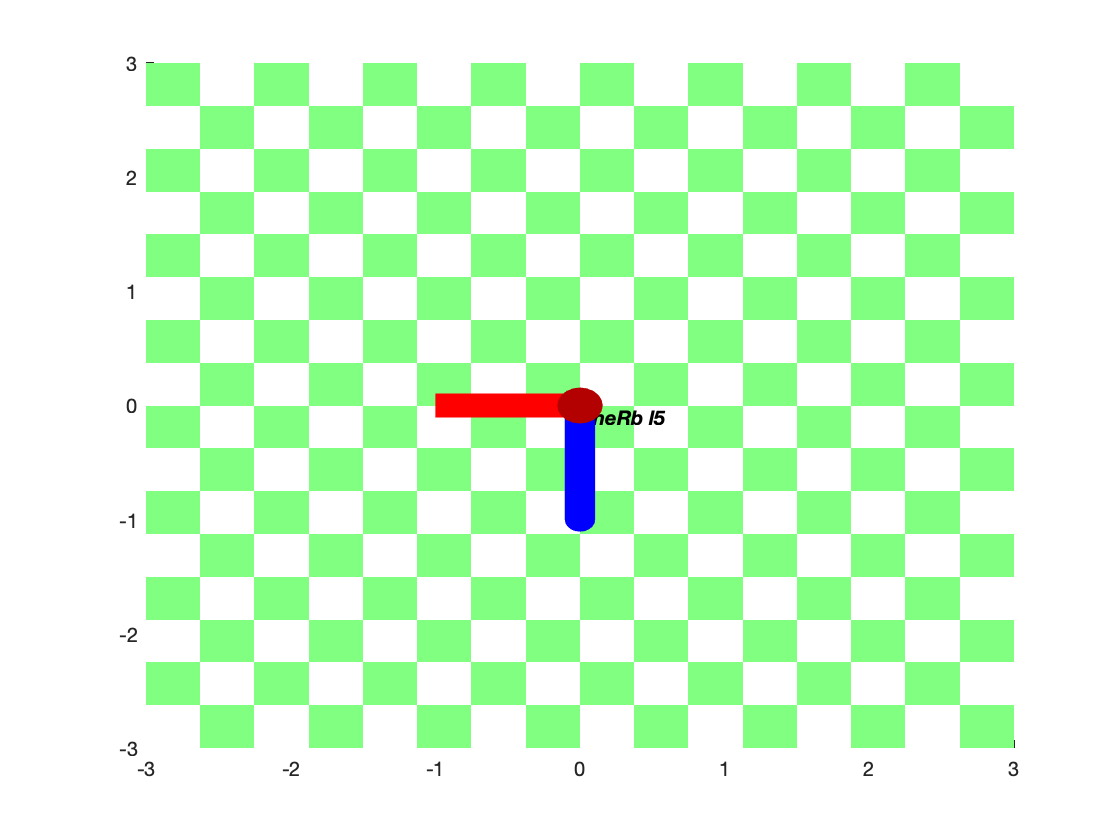

Index exceeds the number of array elements (4).

Error in SerialLink/plot>create_robot (line 469)
            d = norm( d(4:6)-d(1:3) ) / 72;

Error in SerialLink/plot (line 252)
        handle = create_robot(robot, opt);

theRb_l5 = SerialLink (linkss,'name', 'theRb l5', 'gravity', [0 -9.807 0]);

home = [0 0 -90*deg];
hold = [0 0 0];
clear linkss;

figure
theRb_l5.plot(home);

theRb_l5.teach(hold);

theRb_l5.payload(1, [0 0 0]);

jacobian = theRb_l5.jacob0(home);
G = theRb_l5.gravload(home);
torque_home = jacobian.*G

jacobian2 = theRb_l5.jacob0(hold);
G2 = theRb_l5.gravload(hold);
torque_hold = jacobian2.*G2